## Global Variables

% UR5e connection.
vm_host = '127.0.0.1';
real_host = '192.168.0.100';
port = 30003;
home = [-588.53, -133.30, 371.91, 2.2214, -2.2214, 0.00];

% DH parameters.
a = [0, -0.425, -0.3922, 0, 0, 0];
d = [0.1625, 0, 0, 0.1333, 0.0997, 0.0996];
alpha = [pi/2, 0, 0, pi/2, -pi/2, 0];

% Joint variable sets.
theta_A = deg2rad([-90, -173, 132, 220, 0, 0]); % rad.
theta_B = deg2rad([-90, -60, 90, 0, 90, 0]);    % rad.

## Part A.2

The frame transformations of $A_{i}$ for $i \in [1, 6]$ relative to the previous frame are:


$${}^{i - 1}T_{i} = \pmatrix{
    \cos(A_{i}) & -\sin(A_{i}) \cos(\alpha_{i}) & \sin(A_{i}) \sin(\alpha_{i}) & a_{i} \cos(A_{i}) \cr
    \sin(A_{i}) & \cos(A_{i}) \cos(\alpha_{i}) & -\cos(A_{i}) \sin(\alpha_{i}) & a_{i} \sin(A_{i}) \cr
    0 & \sin(\alpha_{i}) & \cos(\alpha_{i}) & d_{i} \cr
    0 & 0 & 0 & 1 \cr
}$$


The frame transformations of a frame $i \in [1, 6]$ relative to the base frame are:


$$\begin{array}{rcl}
{}^{0}T_{1} &=& {}^{0}T_{1} &=& {}^{0}T_{1} \\
{}^{0}T_{2} &=& {}^{0}T_{1} \times {}^{1}T_{2} &=& {}^{0}T_{1} \times {}^{1}T_{2} \\
{}^{0}T_{3} &=& {}^{0}T_{1} \times {}^{1}T_{2} \times {}^{2}T_{3} &=& {}^{0}T_{2} \times {}^{2}T_{3} \\
{}^{0}T_{4} &=& {}^{0}T_{1} \times {}^{1}T_{2} \times {}^{2}T_{3} \times {}^{3}T_{4} &=& {}^{0}T_{3} \times {}^{3}T_{4} \\
{}^{0}T_{5} &=& {}^{0}T_{1} \times {}^{1}T_{2} \times {}^{2}T_{3} \times {}^{3}T_{4} \times {}^{4}T_{5} &=& {}^{0}T_{4} \times {}^{4}T_{5} \\
{}^{0}T_{6} &=& {}^{0}T_{1} \times {}^{1}T_{2} \times {}^{2}T_{3} \times {}^{3}T_{4} \times {}^{4}T_{5} \times {}^{5}T_{6} &=& {}^{0}T_{5} \times {}^{5}T_{6} \\
\end{array}$$


The frame transformations according to $A$ are:

T_A = compute_frame_transforms(theta_A, a, d, alpha)

T_A = T_A(:,:,1) =

    0.0000    0.0000   -1.0000         0
   -1.0000    0.0000   -0.0000         0
         0    1.0000    0.0000    0.1625
         0         0         0    1.0000


T_A(:,:,2) =

   -0.0000   -0.0000   -1.0000    0.0000
    0.9925   -0.1219   -0.0000   -0.4218
   -0.1219   -0.9925    0.0000    0.2143
         0         0         0    1.0000


T_A(:,:,3) =

    0.0000    0.0000   -1.0000    0.0000
   -0.7547   -0.6561   -0.0000   -0.1258
   -0.6561    0.7547    0.0000    0.4716
         0         0         0    1.0000


T_A(:,:,4) =

   -0.0000   -1.0000    0.0000   -0.1333
    0.9998   -0.0000   -0.0175   -0.1258
    0.0175    0.0000    0.9998    0.4716
         0         0         0    1.0000


T_A(:,:,5) =

   -0.0000   -0.0000   -1.0000   -0.1333
    0.9998    0.0175   -0.0000   -0.1276
    0.0175   -0.9998    0.0000    0.5713
         0         0         0    1.0000


T_A(:,:,6) =

   -0.0000   -0.0000   -1.0000   -0.2329
    0.9998    0.0175   -0.0000   -0.127

The frame transformations according to $B$ are:

T_B = compute_frame_transforms(theta_B, a, d, alpha)

T_B = T_B(:,:,1) =

    0.0000    0.0000   -1.0000         0
   -1.0000    0.0000   -0.0000         0
         0    1.0000    0.0000    0.1625
         0         0         0    1.0000


T_B(:,:,2) =

   -0.0000    0.0000   -1.0000    0.0000
   -0.5000   -0.8660   -0.0000    0.2125
   -0.8660    0.5000    0.0000    0.5306
         0         0         0    1.0000


T_B(:,:,3) =

    0.0000    0.0000   -1.0000   -0.0000
   -0.8660    0.5000   -0.0000    0.5522
    0.5000    0.8660    0.0000    0.3345
         0         0         0    1.0000


T_B(:,:,4) =

    0.0000   -1.0000   -0.0000   -0.1333
   -0.8660   -0.0000   -0.5000    0.5522
    0.5000    0.0000   -0.8660    0.3345
         0         0         0    1.0000


T_B(:,:,5) =

   -1.0000    0.0000   -0.0000   -0.1333
   -0.0000    0.5000    0.8660    0.5023
    0.0000    0.8660   -0.5000    0.2481
         0         0         0    1.0000


T_B(:,:,6) =

   -1.0000    0.0000   -0.0000   -0.1333
   -0.0000    0.5000    0.8660    0.588

## Part A.3

The forward kinematic solution, ${}^{0}T_{6}$, for joint variable set $A$ is:

T_A(:, :, 6)

ans =    -0.0000   -0.0000   -1.0000   -0.2329
    0.9998    0.0175   -0.0000   -0.1276
    0.0175   -0.9998    0.0000    0.5713
         0         0         0    1.0000


The forward kinematic solution, ${}^{0}T_{6}$, for joint variable set $B$ is:

T_B(:, :, 6)

ans =    -1.0000    0.0000   -0.0000   -0.1333
   -0.0000    0.5000    0.8660    0.5886
    0.0000    0.8660   -0.5000    0.1983
         0         0         0    1.0000


## Part A.4

The forward kinematic solutions were verified with `fkine.`

% Create links from DH parameters.
L(1) = Link('revolute', 'd', d(1), 'a', a(1), 'alpha', alpha(1));
L(2) = Link('revolute', 'd', d(2), 'a', a(2), 'alpha', alpha(2));
L(3) = Link('revolute', 'd', d(3), 'a', a(3), 'alpha', alpha(3));
L(4) = Link('revolute', 'd', d(4), 'a', a(4), 'alpha', alpha(4));
L(5) = Link('revolute', 'd', d(5), 'a', a(5), 'alpha', alpha(5));
L(6) = Link('revolute', 'd', d(6), 'a', a(6), 'alpha', alpha(6));
links = SerialLink(L);

% Perform forward kinematics from joint variable sets A and B.
T_A_verified = links.fkine(theta_A)

 

T_A_verified = 
         0         0        -1   -0.2329
    0.9998    0.0175         0   -0.1276
    0.0175   -0.9998         0    0.5713
         0         0         0         1


T_B_verified = links.fkine(theta_B)

 

T_B_verified = 
        -1         0         0   -0.1333
         0    0.5000    0.8660    0.5886
         0    0.8660   -0.5000    0.1983
         0         0         0         1


## Part A.5

For $A$:

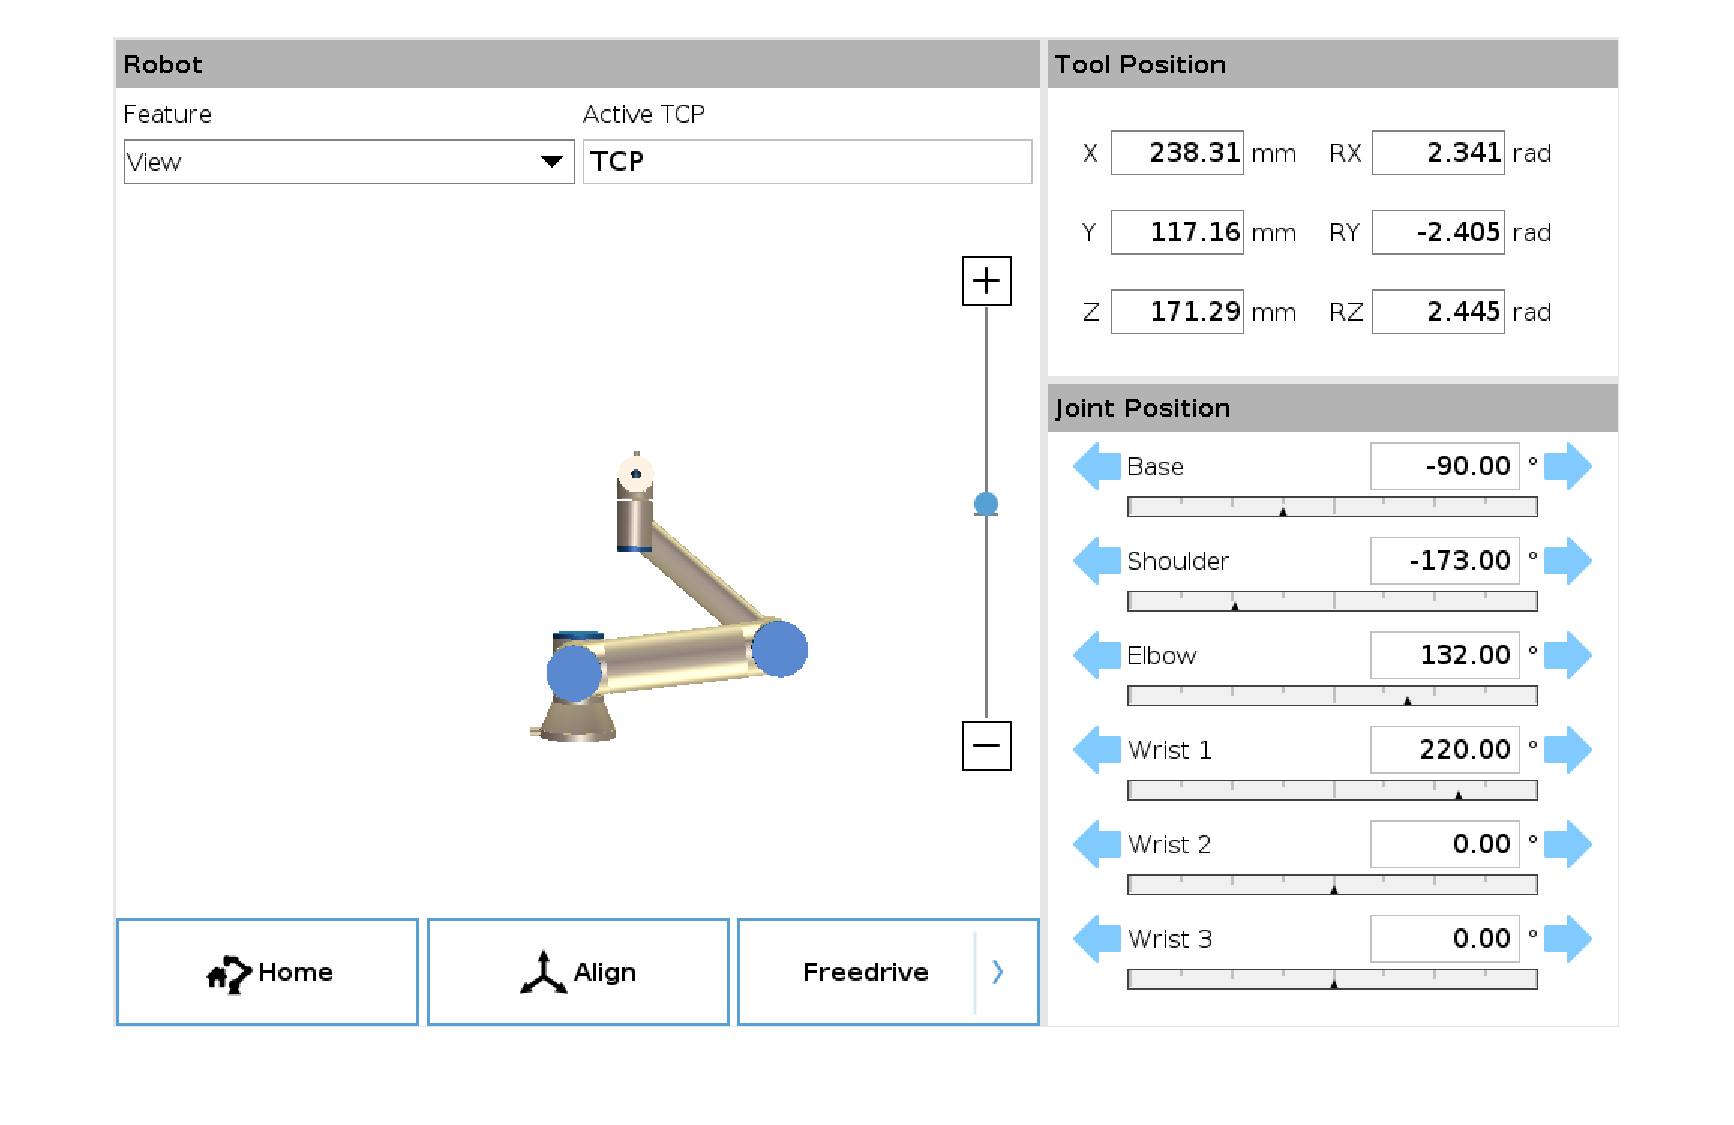

imshow("A_sim_verified.png");

For $B$:

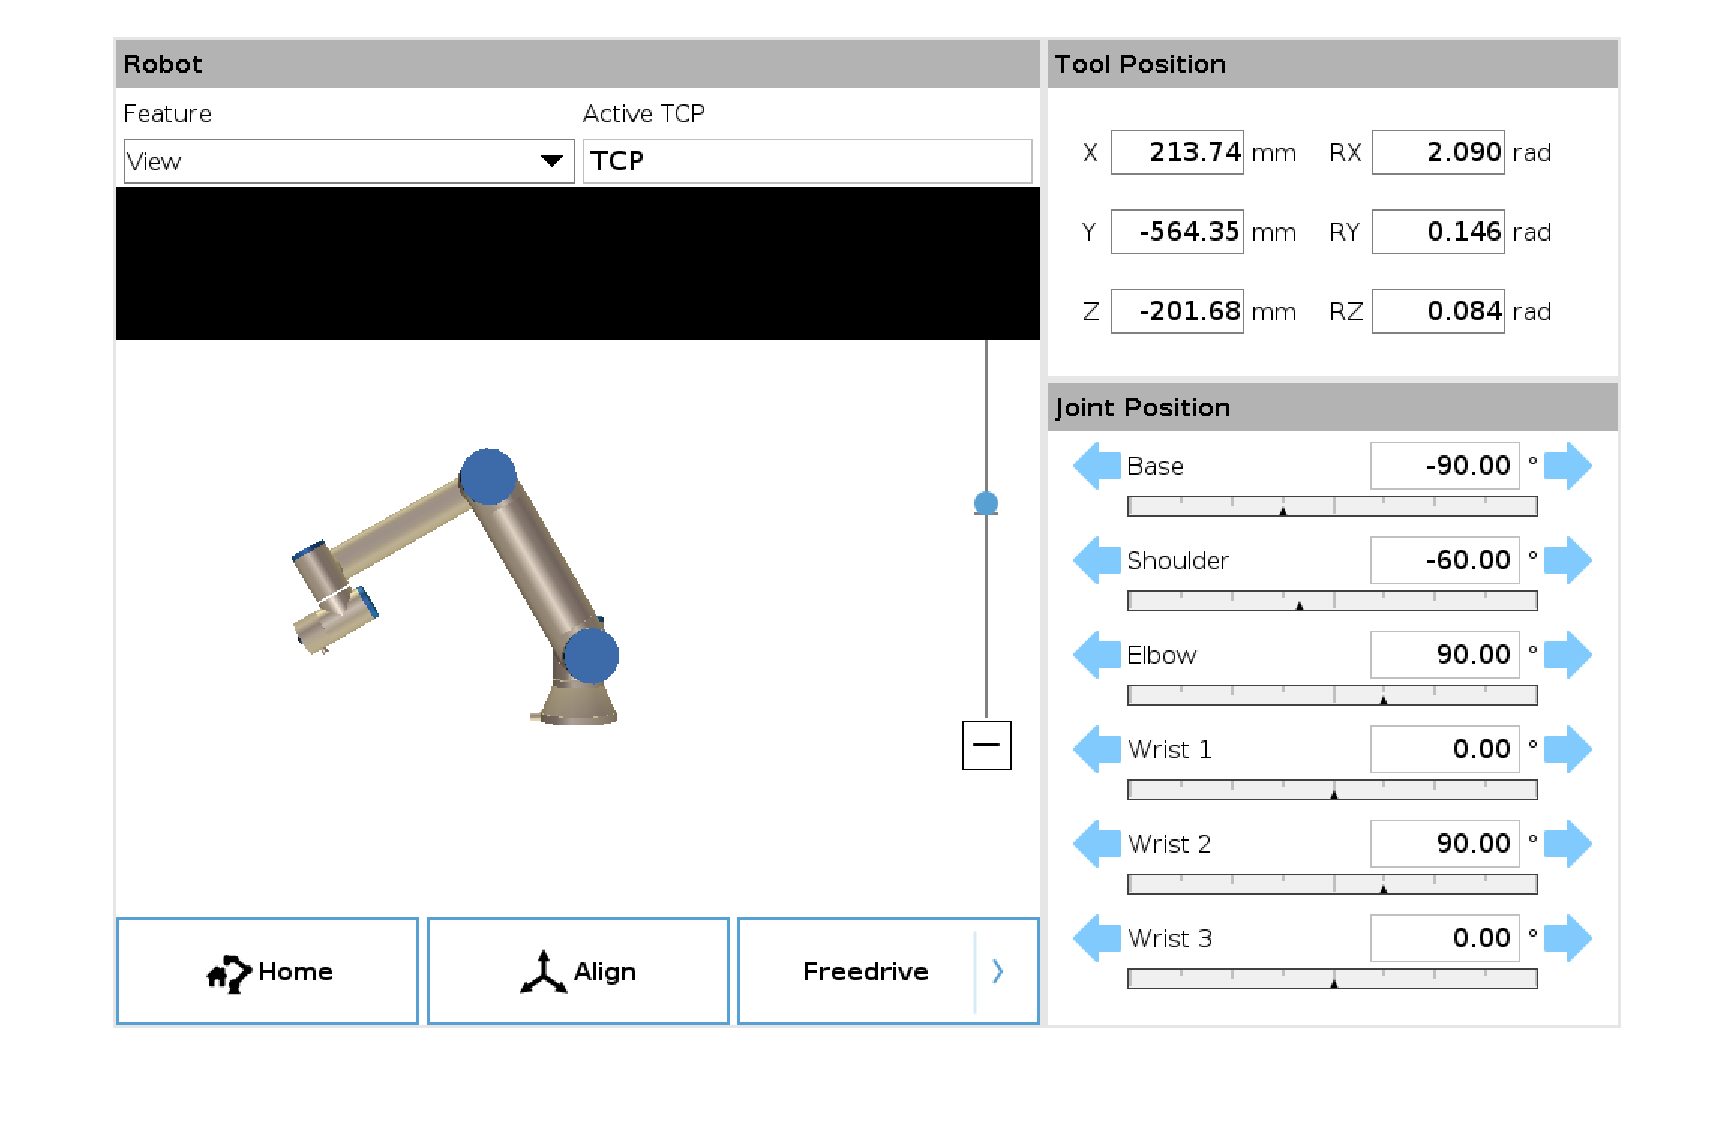

imshow("B_sim_verified.png");

## Part B.1.a

The Jacobian matrix is a generalisation of all of the first-order partial derivatives of a function, $f: \mathbb{R}^{N} \rightarrow \mathbb{R}^{M}$, with respect to a given point, $x$:


$$J = \pmatrix{\frac{\partial\vec{f}}{\partial x_1} & \dots & \frac{\partial\vec{f}}{\partial x_n}} = \pmatrix{\frac{\partial f_{1}}{\partial x_{1}} & ... & \frac{\partial f_{1}}{\partial x_{n}} \cr
        \vdots & \ddots & \vdots \cr
        \frac{\partial f_{m}}{\partial x_{1}} & ... & \frac{\partial f_{m}}{\partial x_{n}}}$$


The Jacobian matrix can intuitively be understood as representing the differential of $f$ at every point where $f$ is differentiable.

The inverse Jacobian matrix is the Jacobian of an invertible function, $f: \mathbb{R}^{N} \leftarrow \mathbb{R}^{M}$:


$$J^{-1}_{f} = J_{f^{-1}}$$


In the context of robotic arms, the Jacobian matrix is used to transform a vector of joint angular velocities to a vector of end effector velocities at a set of joint angular positions (i.e. perform forward kinematics). The inverse Jacobian matrix is used to transform a vector of end effector velocities to a vector of joint angular velocities at a set of joint angular positions (i.e. perform inverse kinematics).

As the Jacobian matrix enables forward and inverse kinematics, control systems using joint angular velocities or end effector velocities can trivially be implemented and utilised. For example, a robotic arm operator may want to spray paint a surface such that the paint is "even". It is infeasible for the operator to know the required joint angular velocities to ensure an "even" paint. However, it is feasible for the operator to know the velocity of the spray painting tool to maintain an "even" paint, so the robotic arm will be controlled by end effector velocities.

## Part B.1.b

Let:

- ${}^{0}z_{i}$ be the angular displacement vector of frame $i$ with respect to the base frame.

- ${}^{0}o_{i}$ be the translational displacement vector of frame $i$ with respect to the base frame.

So:

- 
$${}^{0}z_{i} = {}^{0}T_{i}(\text{row}=1,2,3)(\text{col}=3)$$


- 
$${}^{0}o_{i} = {}^{0}T_{i}(\text{row}=1,2,3)(\text{col}=4)$$


- 
$${}^{0}z_{0} = \pmatrix{0 \cr 0 \cr 1}$$


- 
$${}^{0}o_{0} = \pmatrix{0 \cr 0 \cr 0}$$


So (for a revolute joint $i \in [1, n]$):


$$J_{i} = \pmatrix{
{}^{0}z_{i - 1} \times \left({}^{0}o_{n} - {}^{0}o_{i - 1} \right) \cr
{}^{0}z_{i - 1}
}$$



$$\therefore J = \pmatrix{J_{v} \cr J_{w}} = \pmatrix{J_{1} & \dots & J_{n}}$$


For $A$, the Jacobian matrix, angular, and translational displacement matrices are:

[J_A, z_A, o_A] = compute_jacobian(T_A)

J_A =     0.1276   -0.0000   -0.0000   -0.0000   -0.0000         0
   -0.2329    0.4088    0.3570    0.0997   -0.0996   -0.0000
         0    0.1276   -0.2943    0.0017   -0.0017   -0.0000
         0   -1.0000   -1.0000   -1.0000    0.0000   -1.0000
         0   -0.0000   -0.0000   -0.0000   -0.0175   -0.0000
    1.0000    0.0000    0.0000    0.0000    0.9998    0.0000


z_A = z_A(:,:,1) =

     0
     0
     1


z_A(:,:,2) =

   -1.0000
   -0.0000
    0.0000


z_A(:,:,3) =

   -1.0000
   -0.0000
    0.0000


z_A(:,:,4) =

   -1.0000
   -0.0000
    0.0000


z_A(:,:,5) =

    0.0000
   -0.0175
    0.9998


z_A(:,:,6) =

   -1.0000
   -0.0000
    0.0000


z_A(:,:,7) =

   -1.0000
   -0.0000
    0.0000


o_A = o_A(:,:,1) =

     0
     0
     0


o_A(:,:,2) =

         0
         0
    0.1625


o_A(:,:,3) =

    0.0000
   -0.4218
    0.2143


o_A(:,:,4) =

    0.0000
   -0.1258
    0.4716


o_A(:,:,5) =

   -0.1333
   -0.1258
    0.4716


o_A(:,:,6) =

   -0.1333
   -0.1276
    0.5713


o_A(:,:,7) =

   -0.2329
   -0.1276
    0.5713


For $B$, the Jacobian matrix, angular, and translational displacement matrices are:

[J_B, z_B, o_B] = compute_jacobian(T_B)

J_B =    -0.5886   -0.0000   -0.0000    0.0000    0.0996    0.0000
   -0.1333    0.0358   -0.3322   -0.1361    0.0000    0.0000
         0   -0.5886   -0.3761   -0.0364   -0.0000    0.0000
         0   -1.0000   -1.0000   -1.0000   -0.0000   -0.0000
         0   -0.0000   -0.0000   -0.0000   -0.5000    0.8660
    1.0000    0.0000    0.0000    0.0000   -0.8660   -0.5000


z_B = z_B(:,:,1) =

     0
     0
     1


z_B(:,:,2) =

   -1.0000
   -0.0000
    0.0000


z_B(:,:,3) =

   -1.0000
   -0.0000
    0.0000


z_B(:,:,4) =

   -1.0000
   -0.0000
    0.0000


z_B(:,:,5) =

   -0.0000
   -0.5000
   -0.8660


z_B(:,:,6) =

   -0.0000
    0.8660
   -0.5000


z_B(:,:,7) =

   -0.0000
    0.8660
   -0.5000


o_B = o_B(:,:,1) =

     0
     0
     0


o_B(:,:,2) =

         0
         0
    0.1625


o_B(:,:,3) =

    0.0000
    0.2125
    0.5306


o_B(:,:,4) =

   -0.0000
    0.5522
    0.3345


o_B(:,:,5) =

   -0.1333
    0.5522
    0.3345


o_B(:,:,6) =

   -0.1333
    0.5023
    0.2481


o_B(:,:,7) =

   -0.1333
    0.5886
    0.1983


## Part B.1.c

The Jacobian is verified using `jacob0.`

J_A_verified = links.jacob0(theta_A)

J_A_verified =     0.1276   -0.0000   -0.0000   -0.0000    0.0000         0
   -0.2329    0.4088    0.3570    0.0997   -0.0996         0
    0.0000    0.1276   -0.2943    0.0017   -0.0017         0
         0   -1.0000   -1.0000   -1.0000    0.0000   -1.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0175   -0.0000
    1.0000    0.0000    0.0000    0.0000    0.9998    0.0000


J_B_verified = links.jacob0(theta_B)

J_B_verified =    -0.5886   -0.0000   -0.0000    0.0000    0.0996         0
   -0.1333    0.0358   -0.3322   -0.1361    0.0000         0
   -0.0000   -0.5886   -0.3761   -0.0364   -0.0000         0
         0   -1.0000   -1.0000   -1.0000   -0.0000   -0.0000
         0   -0.0000   -0.0000   -0.0000   -0.5000    0.8660
    1.0000    0.0000    0.0000    0.0000   -0.8660   -0.5000


## Part B.1.d

Consider the end effector velocity with a velocity of ${}^{0}\dot{d}_{6}$ and passing through $A$ where:


$${}^{0}\dot{d}_{6} = \pmatrix{0.25 \cr 0 \cr 0 \cr 0 \cr 0 \cr 0}$$


The instantaneous joint velocities, $\dot{\theta}_A = J^{-1}_{A} \cdot {}^{0}\dot{d}_{6}$, of the end effector is:

d_dot_A_6 = [0.25; 0; 0; 0; 0; 0];
theta_dot_A = pinv(J_A) * d_dot_A_6

theta_dot_A =     1.9236
    0.4923
    0.2234
   -0.2458
   -1.9233
   -0.4698


## Part B.1.e

Checking the determinant of $J_{A}$ shows that it is zero.

det(J_A)

ans = -1.0264e-35

Therefore, $\dot{\theta}_A$ is not reasonable as $J_A$ is singular.

The other argument (for marks) is that $\dot{\theta}_{A}$ (in $\text{rad}/s$) is well within the safety limits of $191 {}^{\circ} / s = 3.33 \text{ rad}/s$ therefore $\dot{\theta}_{A}$ is reasonable.

## Part B.2

Consider the joint angular velocities at $B$:


$$\dot{\theta}_{B} = \pmatrix{1 \cr 0.1 \cr 0.1 \cr 0.1 \cr 0.1 \cr 0.1}$$


The end effector velocity, ${}^{0}\dot{d}_{6} = J_{B} \cdot \dot{\theta}_{B}$, is therefore:

theta_dot_B = [1; 0.1; 0.1; 0.1; 0.1; 0.1];
d_dot_B_6 = J_B * theta_dot_B

d_dot_B_6 =    -0.5786
   -0.1766
   -0.1001
   -0.3000
    0.0366
    0.8634


The values are reasonable since $\dot{\theta}_{B}$ (in $\text{rad}/s$) is well within the safety limits of $3.33 \text{ rad}/s$ and $J_{B}$ is not singular.

det(J_B)

ans = -0.0837

## Part C

% Define poses for Part C.
pose1 = [-588.53, -133.30, 100, 2.2214, -2.2214, 0]; % mm and rad/s.
pose2 = [-688.53, -133.30, 100, 2.2214, -2.2214, 0]; % mm and rad/s.
pose3 = [-688.53, -233.30, 100, 2.2214, -2.2214, 0]; % mm and rad/s.
pose4 = [-588.53, -233.30, 100, 2.2214, -2.2214, 0]; % mm and rad/s.

% Default move parameters.
a = 0.1;
v = 0.05;

## Part C.1

Drawing the trajectory of poses 1, 2, 3, 4 using `movel`.

% Create moves from poses.
move1 = UR5eMove('l', pose1, 'pose', a, v);
move2 = UR5eMove('l', pose2, 'pose', a, v);
move3 = UR5eMove('l', pose3, 'pose', a, v);
move4 = UR5eMove('l', pose4, 'pose', a, v);
move5 = UR5eMove('l', pose1, 'pose', a, v);

% Execute moves.
ur5e_l = UR5e(vm_host, port, pose1);

UR5e connection Established!
Socket Disconnected!


Program started.
Succeeded!
Moving to [-6.885300e+02, -1.333000e+02, 100, 2.221400e+00, -2.221400e+00, 0]...


Succeeded!
Moving to [-6.885300e+02, -2.333000e+02, 100, 2.221400e+00, -2.221400e+00, 0]...
Succeeded!
Moving to [-5.885300e+02, -2.333000e+02, 100, 2.221400e+00, -2.221400e+00, 0]...
Succeeded!
Moving to [-5.885300e+02, -1.333000e+02, 100, 2.221400e+00, -2.221400e+00, 0]...
Succeeded!
Succeeded!
Program completed.


ur5e_l.add_move(move1, move2, move3, move4, move5);
ur5e_l.execute();

## Part C.2

Drawing the trajectory of poses 1, 2, 3, 4 using `movej`.

% Create moves from poses.
move1 = UR5eMove('j', pose1, 'pose', a, v);
move2 = UR5eMove('j', pose2, 'pose', a, v);
move3 = UR5eMove('j', pose3, 'pose', a, v);
move4 = UR5eMove('j', pose4, 'pose', a, v);
move5 = UR5eMove('j', pose1, 'pose', a, v);

% Execute moves.
ur5e_j = UR5e(vm_host, port, pose1);

UR5e connection Established!
Socket Disconnected!


ur5e_j.add_move(move1, move2, move3, move4, move5);
ur5e_j.execute();

Program started.
Succeeded!
Moving to [-6.885300e+02, -1.333000e+02, 100, 2.221400e+00, -2.221400e+00, 0]...
Succeeded!
Moving to [-6.885300e+02, -2.333000e+02, 100, 2.221400e+00, -2.221400e+00, 0]...
Succeeded!
Moving to [-5.885300e+02, -2.333000e+02, 100, 2.221400e+00, -2.221400e+00, 0]...
Succeeded!
Moving to [-5.885300e+02, -1.333000e+02, 100, 2.221400e+00, -2.221400e+00, 0]...
Succeeded!
Succeeded!
Program completed.


## Part C.3.a

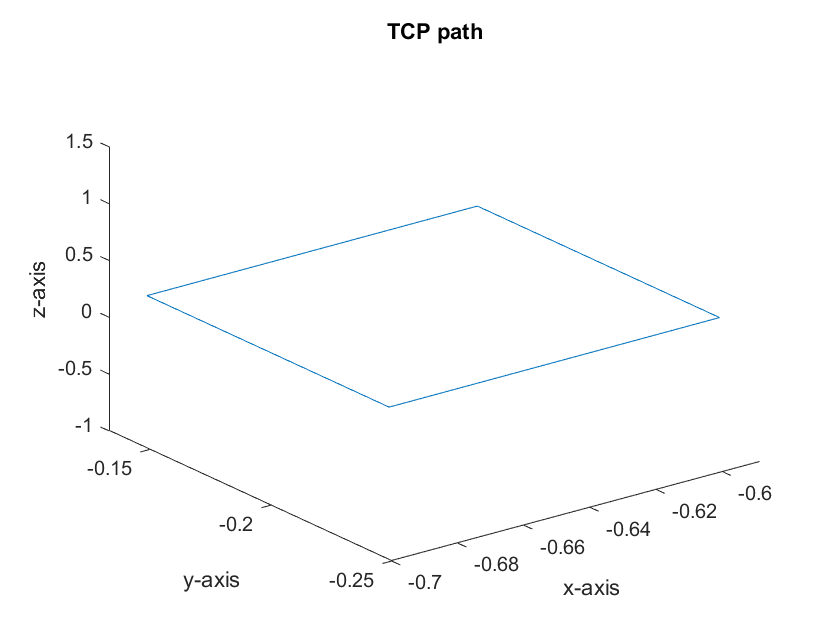

% Draw TCP paths.
ur5e_l.draw(1, 0, 0, 0, 0);

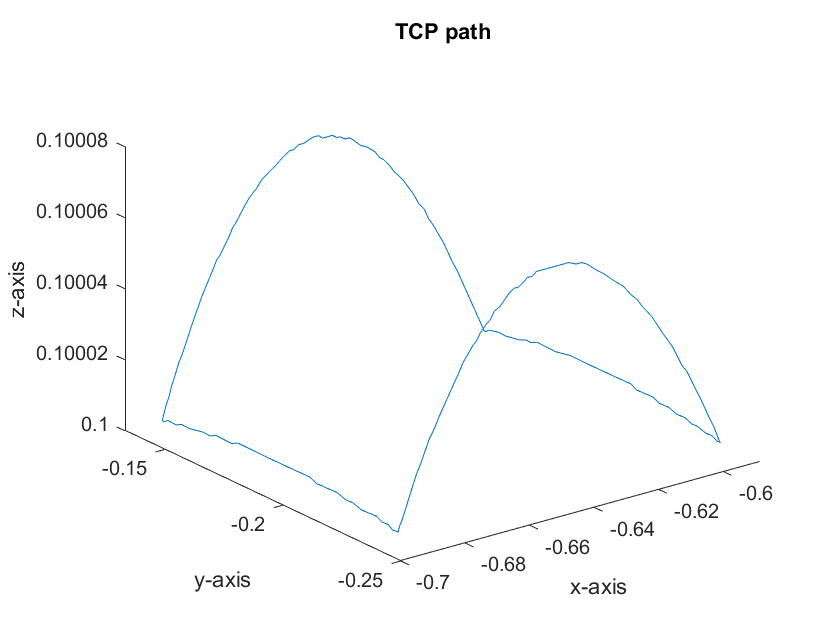

ur5e_j.draw(1, 0, 0, 0, 0);

The TCP path differs in that `movej` is polynomial and `movel` is linear. It is observed for `movej`, `move2` and `move4` have greater "height" than `move1` and `move3`.

## Part C.3.b

## Part C.3.c

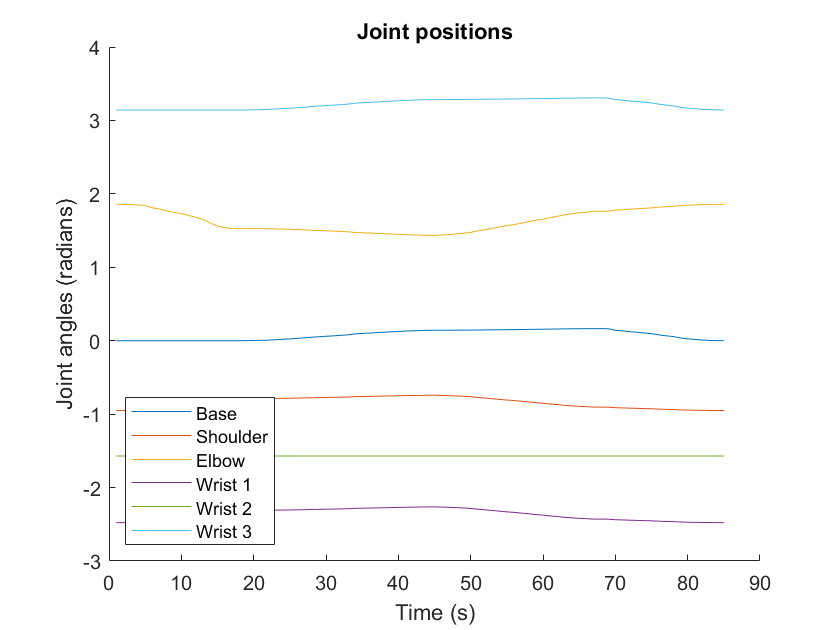

% Draw joint positions.
ur5e_l.draw(0, 1, 0, 0, 0);

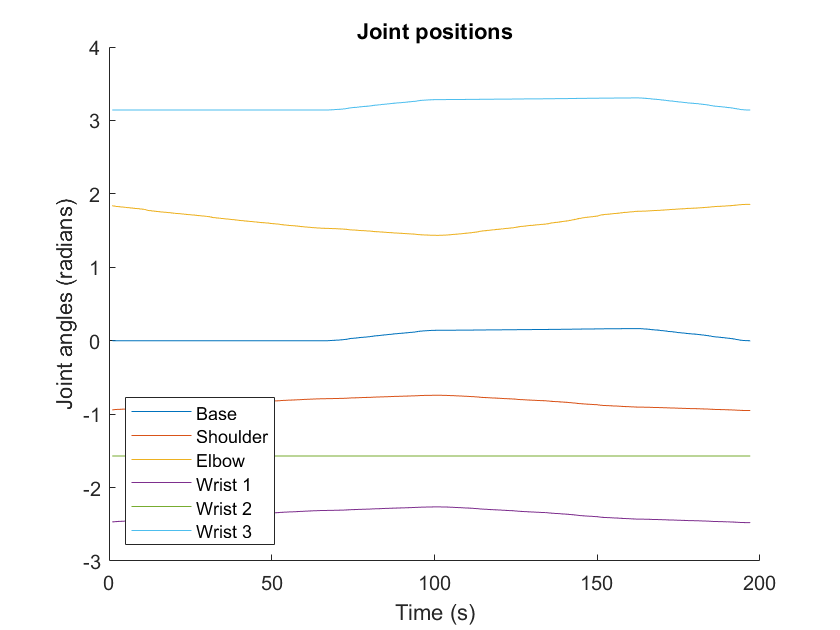

ur5e_j.draw(0, 1, 0, 0, 0);

It is observed that the `movej` sequence had a duration of ~210 s whereas the `movel` sequence had a duration of ~75 s. The joint positions for both `movej` and `movel` are similar and nothing of significance is noted.

## Part C.3.d

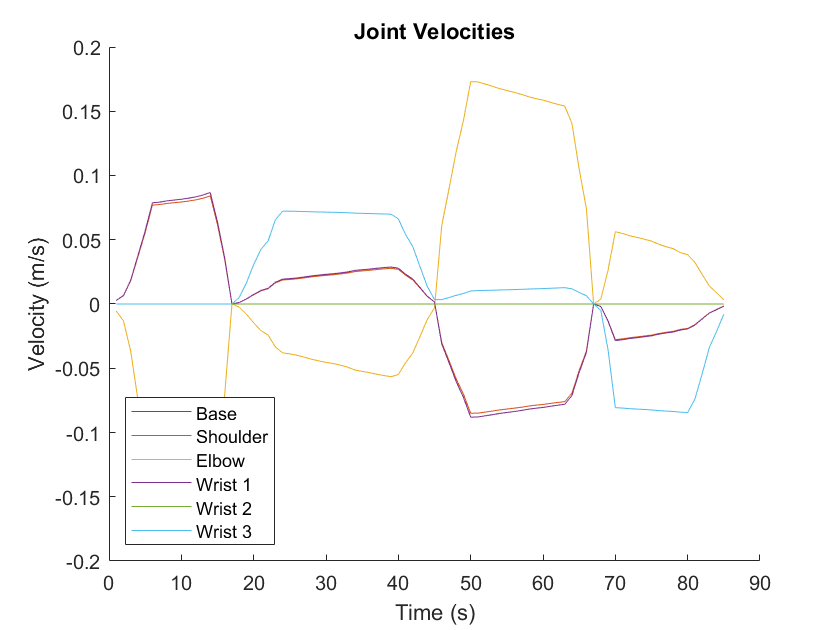

% Draw joint velocities.
ur5e_l.draw(0, 0, 1, 0, 0);

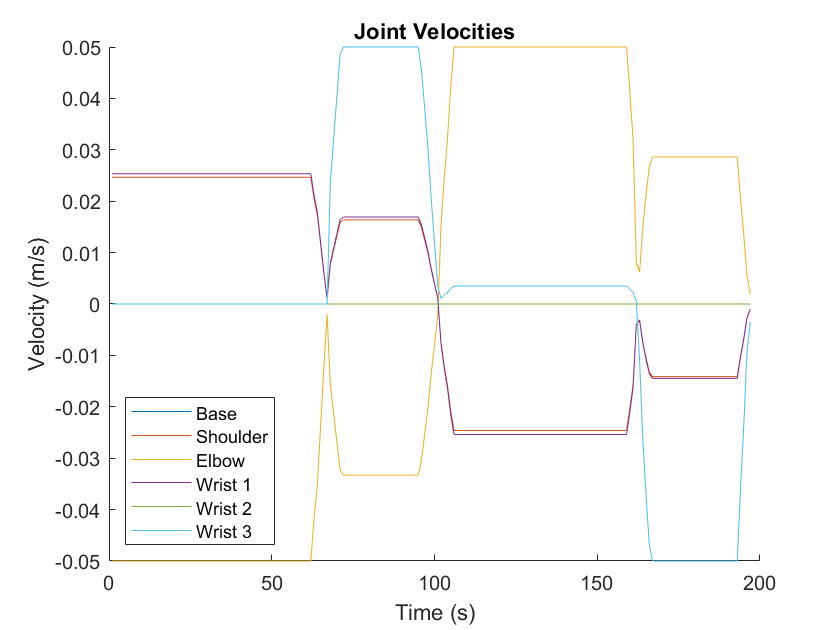

ur5e_j.draw(0, 0, 1, 0, 0);

The joint velocities for `movel` are characterised by non-constant angular velocities. The joint velocities for `movej` are characterised by constant angular velocities.

## Part C.3.e

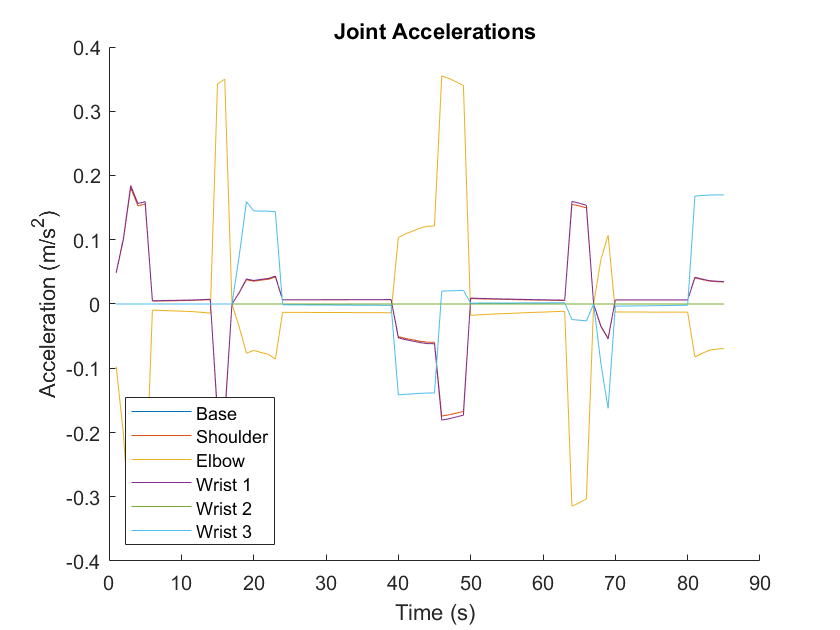

% Draw joint accelerations.
ur5e_l.draw(0, 0, 0, 1, 0);

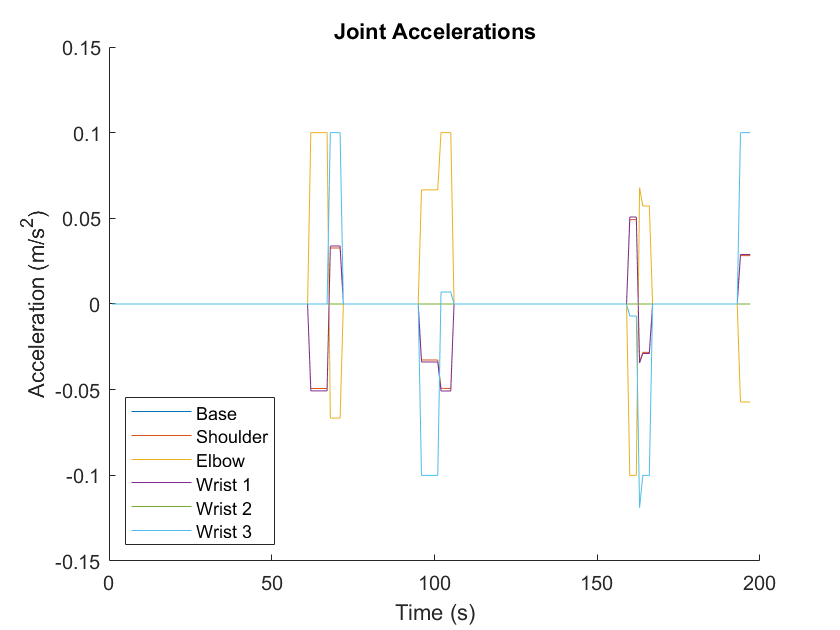

ur5e_j.draw(0, 0, 0, 1, 0);

The joint accelerations for `movel` are characterised by more periods of non-zero accleration. The joint accelerations for `movej` are characterised by more periods of zero acceleration.

## Part C.4

It is expected that the real UR5e robot will generate data with lots of noise due to momentum, motor vibrations, and the cantilever effect.

## Part C.5

By inspection of the joint velocity plots and observing that velocity traces are only linear, the UR5e employs a trapezoidal trajectory generation method.

The advantages of trapezoidal trajectory planning are:

- Greater efficiency due to simpler computation due to lower degree kinematics.

The disadvantages of trapezoidal trajectory planning are:

- Slower in achieving the pose due to lower degree kinematics.

The advantages of polynomial trajectory planning are:

- Faster in achieving the pose due to higher degree kinematics.

The disadvantages of polynomial trajectory planning are:

- Low mean velocity can occur which is power inefficient.

- Substantial overshoot can occur with a large initial velocity and zero final velocity causing the robot to miss its pose.

Trapezoidal trajectory planning is preferred due to its greater computational and power efficiency, does not overshoot, and is sufficient in achieving a pose within a reasonable time.

## Part C.6

`movel` is used if the TCP is required to linearly move to a pose at a constant velocity. The advantage of `movel` is:

- Greater TCP positioning and velocity control.

The disadvantage of `movel` is:

- Slow operation since the TCP is required to move at a constant velocity.

Therefore, `movel` is useful for applications such as:

- Lifting and delivering payloads to ensure stable picking and placing.

- Machining operations e.g. welding, deburring, cutting to ensure consistent machining quality.

`movej` is used if the TCP is required to move to a pose as quickly as possible. The advantage of `movej` is:

- Fast operation since the all joints reach their positions as fast as possible.

The disadvantage of `movej` is:

- Worse TCP positioning and velocity control.

Therefore, `movej` is useful for applications such as:

- Optimising movement to increase process productivity e.g. moving payloads.

The decision between selecting `movel` and `movej` operations is ultimately a trade-off between velocity control and time optimisation requirements.

## Part D

% Define poses for part D.
pose_C = [100, -127.58, 571.29, -1.571, -0.017, 1.57]; % mm and rad/s.

% Perform movements within 5 s.
a = 1.2;
v = 0.25;
t = 5;
r = 0;

## Part D.1

% Create moves from poses.
move1 = UR5eMove('j', theta_A, 'joint');
move2 = UR5eMove('j', pose_C, 'pose', a, v, t, r);

% Execute moves.
ur5e_s_j = UR5e(vm_host, port, home);
ur5e_s_j.add_move(move1, move2);
ur5e_s_j.execute();

## Part D.2

% Create moves from poses.
move1 = UR5eMove('j', theta_A, 'joint');
move2 = UR5eMove('l', pose_C, 'pose', a, v, t, r);

% Execute moves.
ur5e_s_l = UR5e(vm_host, port, home);
ur5e_s_l.add_move(move1, move2);
ur5e_s_l.execute();

## Part D.3

`movej` was successful in completing `move1` and `move2`. `movel` however encounters a singularity when attempting `move2` as shown in the error message below:

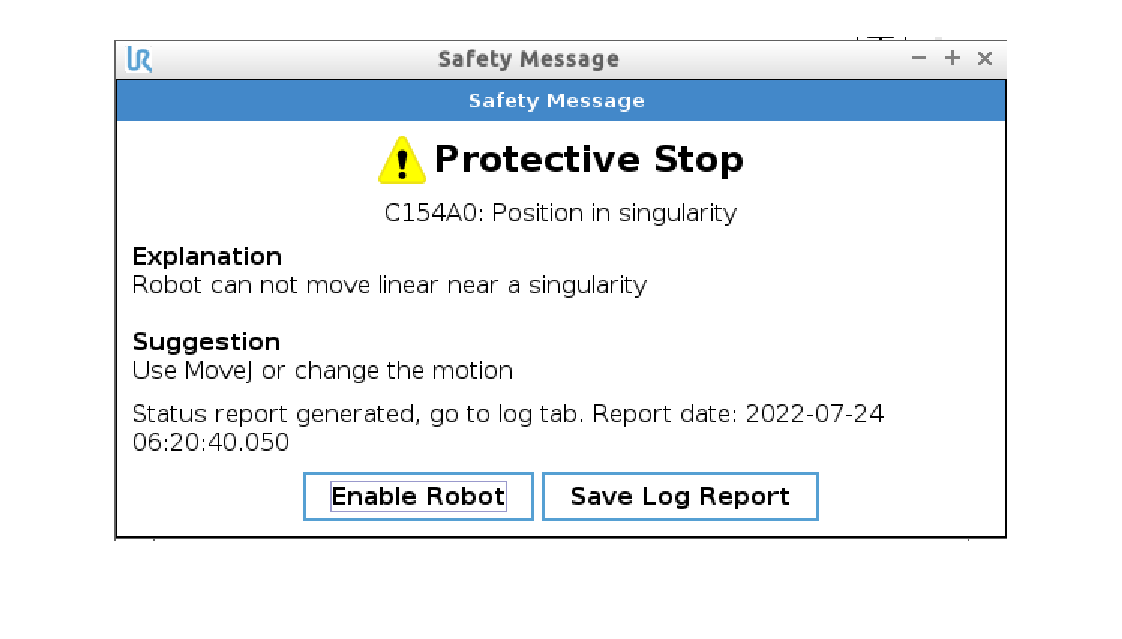

imshow("protective_stop_singularity.png");

This error is due to a shoulder singularity where the wrist centre attempts to move linearly along a path that intersects with the rotational axis of joint 1. This causes unbounded joint velocities which significantly increases power consumption which may cause overvolting and wear of mechanical parts.

## Part D.4

Singularities occur when the determinant of the Jacobian matrix used for forward/inverse kinematics is zero. There are three different types of singularities:

- Wrist.

- Elbow.

- Shoulder.

Wrist singularities occur when the axes of joints 4 and 6 are collinear i.e. $\theta_{5} = 0$. This causes a loss of 1 DOF i.e. causes joints 4 and 6 to rotate in equal and opposite directions resulting in no net (or extremely inefficient) motion for the end effector. This can be handled by:

- implementing a flip-no-flip condition to force $\theta_{5} < 0$ or $\theta_{5} > 0$;

- asserting $\dot{\theta}_{4} \neq -\dot{\theta}_{6}$; or,

- mounting tools at small angles.

Elbow singularities occur when the wrist centre and plane containing joints 2 and 3 are coplanar i.e. $\theta_{3} = 0$. This causes unbounded joint velocities/torques when $\theta_{3}$ approaches zero. This can be handled by:

- implementing an up-down condition to force $\theta_{3} < 0$ or $\theta_{3} > 0$;

- ensuring the wrist centre is not coplanar with the plane containing joints 2 and 3; or,

- mounting tools at small angles.

Shoulder singularities occur when the wrist centre and ${}^{0}z_{1}$ axis are coincident. This causes unbounded joint velocities/torques if the end effector were to traverse a path over the coincident point. This can be handled by:

- asserting the centre point can never be coincident with the ${}^{0}z_{1}$ axis by replotting a better path;

- prefering `movej` to `movel` to minimise the chance of shoulder singularity; or,

- mounting tools at small angles.

Singularities are problematic in industry e.g. moving payloads (e.g. warehouse applications) or performing a linear operation (e.g. welding, spray painting) where elbow and industrial singularities would result in increased power consumption and increased risk of equipment damage.

## Utilities

Helper function to compute frame transforms from DH parameters.

function T = compute_frame_transforms(theta, a, d, alpha)
    % Frame transformations of i relative to i-1.
    T_ij = zeros(4, 4, length(theta));
    for i = 1:length(theta)
        T_ij(:, :, i) = [
            cos(theta(i)), -sin(theta(i)) * cos(alpha(i)), sin(theta(i)) * sin(alpha(i)), a(i) * cos(theta(i));
            sin(theta(i)), cos(theta(i)) * cos(alpha(i)), -cos(theta(i)) * sin(alpha(i)), a(i) * sin(theta(i));
            0, sin(alpha(i)), cos(alpha(i)), d(i);
            0, 0, 0, 1
        ];
    end

    % Frame transformations of i relative to 0.
    T = zeros(4, 4, length(theta));
    T(:, :, 1) = T_ij(:, :, 1);
    for i = 2:length(theta)
        T(:, :, i) = T(:, :, i - 1) * T_ij(:, :, i);
    end
end

Helper function to compute Jacobian matrices from frame transforms.

function [J, z, o] = compute_jacobian(T)
    n = length(T);

    % Get each frame displacement from base frame.
    z = zeros(3, 1, n + 1);
    o = zeros(3, 1, n + 1);
    z(:, :, 1) = [0; 0; 1];
    o(:, :, 1) = [0; 0; 0];
    for i = 1:n
        z(:, :, i + 1) = T(1:3, 3, i)';
        o(:, :, i + 1) = T(1:3, 4, i)';
    end

    % Compute Jacobian.
    J = zeros(6, 6);
    for i = 1:n
        J(:, i) = [cross(z(:, :, i), (o(:, :, n + 1) - o(:, :, i))); z(:, :, i)];
    end
end

Externally defined UR5e class.

classdef UR5e < handle
    properties
        UR5e_handle;
        home = [-588.53, -133.30, 371.91, 2.2214, -2.2214, 0.00]; % [x,y,z,r,p,y]
        tool_height = 80;
        tcp_rotation = [2.2214, -2.2214, 0.00];
        moves = [];
        pose_history = [];
        joint_position_history = [];
        joint_velocity_history = [];
        joint_acceleration_history = [];
        joint_torque_history = [];
    end

    methods
        %% Constructor.
        function obj = UR5e(host, port, home)
            obj.UR5e_handle = rtde(host, port);
            
            if exist('home', 'var')
                obj.home = home;
            end
        end
        
        %% Destructor.
        function delete(obj)
            obj.UR5e_handle.close(); % Close connection.
        end

        %% Move to home.
        function move_to_home(obj)
            obj.UR5e_handle.movej(obj.home);
        end
        
        %% Execute all moves.
        function execute(obj)
            fprintf("Program started.\n");
            obj.move_to_home();
            for i = 1:length(obj.moves)
                pose_as_cell = num2cell(obj.moves(i).pose);
                fprintf("Moving to [%d, %d, %d, %d, %d, %d]...\n", pose_as_cell{:});
                [pose, joint_position, joint_velocity, joint_acceleration, joint_torque] = obj.moves(i).execute();
                obj.pose_history = [obj.pose_history; pose];
                obj.joint_position_history = [obj.joint_position_history; joint_position];
                obj.joint_velocity_history = [obj.joint_velocity_history; joint_velocity];
                obj.joint_acceleration_history = [obj.joint_acceleration_history; joint_acceleration];
                obj.joint_torque_history = [obj.joint_torque_history; joint_torque];
            end
            obj.move_to_home();
            fprintf("Program completed.\n");
        end

        %% Draw the moves.
        function draw(obj, draw_path, draw_joint_position, draw_joint_velocity, draw_joint_acceleration, draw_joint_torque)
            if draw_path
                obj.UR5e_handle.drawPath(obj.pose_history);
            end

            if draw_joint_position
                obj.UR5e_handle.drawJointPositions(obj.joint_position_history);
            end

            if draw_joint_velocity
                obj.UR5e_handle.drawJointVelocities(obj.joint_velocity_history);
            end

            if draw_joint_acceleration
                obj.UR5e_handle.drawJointAccelerations(obj.joint_acceleration_history);
            end

            if draw_joint_torque
                obj.UR5e_handle.drawJointTorques(obj.joint_torque_history);
            end
        end

        %% Queue move.
        function add_move(obj, varargin)
            for i = 2:length(varargin)
                obj.moves = [obj.moves; varargin{i}];
                obj.moves(end).UR5e_handle = obj.UR5e_handle;
            end
        end

        %% Get the TCP position.
        function pose = actual_pose(obj)
            pose = obj.UR5e_handle.actualPosePositions();
        end
    end
end

Externally defined UR5eMove class.

classdef UR5eMove
    properties
        UR5e_handle;
        move_type = 'l'; % l, j, c.
        pose = zeros(1, 6); % [x, y, z, roll, pitch, yaw].
        args = {};
        a; % Tool acceleration.
        v; % Tool velocity.
        t; % Time.
        r; % Blend radius.
        m; % Mode: 0 = unconstrained tool angle, 1 = fixed tool angle.
    end
    
    methods
        %% Constructor.
        function obj = UR5eMove(move_type, pose, jointOrPose, a, v, t, r, m)
            obj.move_type = move_type;
            obj.pose = pose;

            if exist('jointOrPose', 'var')
                obj.args{1} = jointOrPose;
            end
            
            if exist('a', 'var')
                obj.args{2} = a;
            end
            
            if exist('v', 'var')
                obj.args{3} = v;
            end
            
            if exist('t', 'var')
                obj.args{4} = t;
            end
            
            if exist('r', 'var')
                obj.args{5} = r;
            end
            
            if exist('m', 'var')
                obj.args{6} = m;
            end
        end
        
        %% Execute move.
        function [pose, joint_position, joint_velocity, joint_acceleration, joint_torque] = execute(obj)
            if obj.move_type == 'l'
                [pose, joint_position, joint_velocity, joint_acceleration, joint_torque] = obj.UR5e_handle.movel(obj.pose, obj.args{:});
            elseif obj.move_type == 'j'
                [pose, joint_position, joint_velocity, joint_acceleration, joint_torque] = obj.UR5e_handle.movej(obj.pose, obj.args{:});
            elseif obj.move_type == 'c'
                [pose, joint_position, joint_velocity, joint_acceleration, joint_torque] = obj.UR5e_handle.movec(obj.pose, obj.args{:});
            else
                error("Move type is undefined. Expected 'l', 'j', 'c' but got %c", obj.move_type);
            end
        end
    end
end

Function definitions in a script must appear at the end of the file.
Move all statements after the "compute_jacobian" function definition to before the first local function definition.